# Быстрое Преобразование Фурье

## студента: Красницкого Никиты

Суть БПФ с прореживанием по времени по основанию 2 состоит в том, что последовательность, красную 2 m раз можно столько же раз разложить на сумму и разницу дискретного преобразования фурье парных о непарных отчетов. Об этом можно детально прочесть в следующем сайте, с которого и взяты нижепредставленные формулы. [http://ru.dsplib.org/content/fft_dec_in_time/fft_dec_in_time.html](http://ru.dsplib.org/content/fft_dec_in_time/fft_dec_in_time.html)

Так находятся первые N/2 отчетов спектра

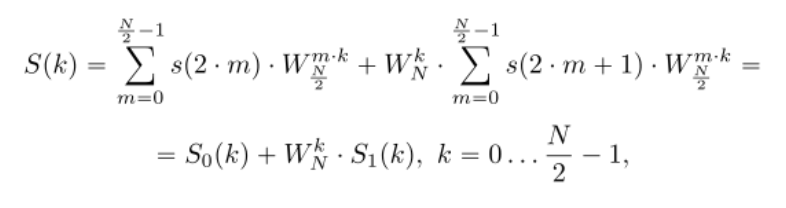

А так находятся оставшиеся N/2 отчета

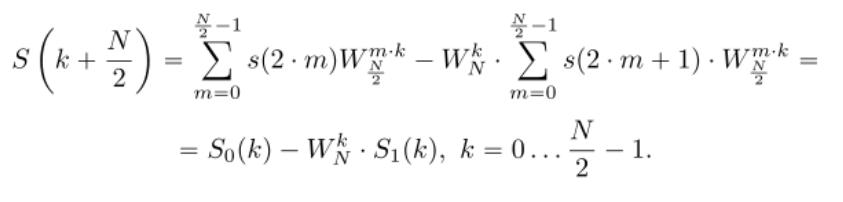

## Принцип работы закоментированного кода:

В функции БПФ я расписал операции с комплексными числами для N = 2, а для остальных случаев (N = 4, 8) была использована рекурсия с учетом switch-case опирающегося на кол-во отчетов входного сигнала. Выходит, что пришедший сигнал из 8ми отчетов дробится на два сигнала по 4 отчета и рекурсией попадает в блок алгоритма ДПФ для N = 4, где сигнал дробится еще раз и посылается в блок ДПФ для N = 2, где сложные комплексные операции расписаны простыми для вычисления - суммой и разницой. Такой алгоритм решения схематически показан ниже.

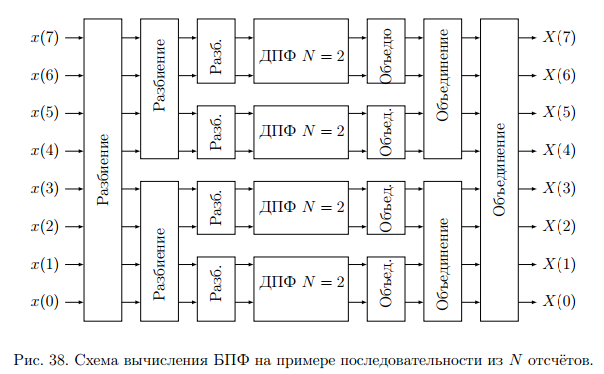

Добавив зависимость от длинны сигнала получил общую формулу для БПФ последовательности у которой кол-во отчетов равно степени двойки. 

clear all
close all

Входная последовательность N = 32

s = [1 1 3 7 4 1 3 -1   1 1 2 2 4 1 3 -1  1 2 3 4 5 6 7 8  1 2 3 4 5 6 7 8];

Нахожу ДПФ своей функцией и встроенной в MATLAB

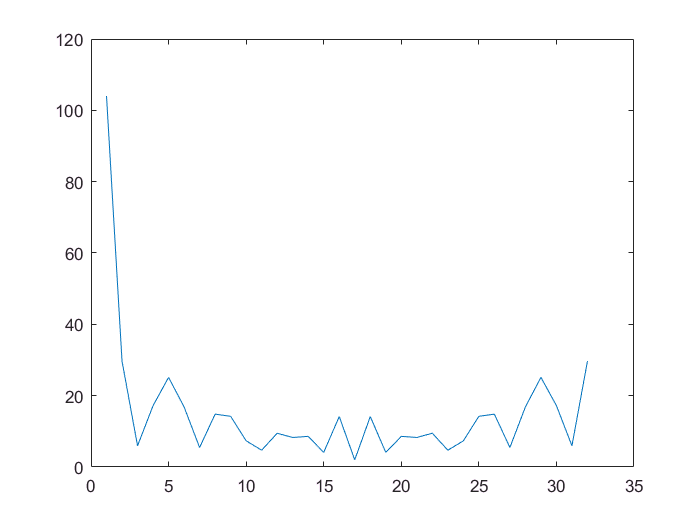

S1 = fft(s);
S2 = DSPf8(s);
plot(abs(S1));

plot(abs(S2));